clear variables;
addPath;

%tempo reduction param
para.kF = 20;
para.redL = 5;
para.reduct = true;

%ACA param
para.nMi = 5;
para.nMa = 10;
para.ini='r';
para.k=8;
para.nIni=1;

%HACA param
para2 = para;
para2.nMi = 4;
para2.nMa = 8;
para2.k=4;
para2.nIni=10;
paraH = [para para2];

%output path
out_path = './output/';
%mkdir(out_path);


%select cluster num
sel_num = 2;

## ACA on Select data (mice) and select clusters

 9347 -> 2575
 8247 -> 2089


 10331 -> 2614
 10046 -> 2681


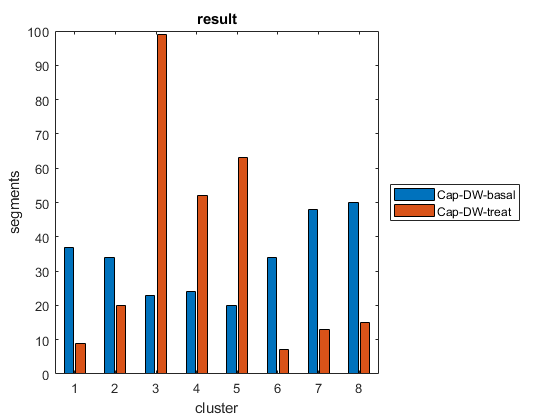

 11875 -> 3040
 9843 -> 2306


 11097 -> 2963
 9270 -> 2390


all_paths = getAllFile('../feat/20210811/');

nX = [];
ns = [];
splits = [];

% multiple
micenames = {'B' , 'DW', 'LKB', 'LW', 'RK', 'SW', 'LKW' , 'MW', 'WT'};
for i=1:size(micenames,2)
    % data process
    micename = micenames{i};
    sel = find(contains(all_paths, ['-',micename,'-']));
    paths=all_paths(sel);
    [X, ends, names] = loadData(paths,para);
    % aca
    K = conKnl(conDist(X, X));
    seg = segIniR(K, para);
    segResult = segAca(K, para, seg);
    % plot result
    [sP, LP, ss, labels] = segPart(segResult.s,segResult.G,ends);
    clusterPlot(labels,names,strcat(out_path,micename,'.png'));
    % select and append 
    sel = largeDiff(labels,sel_num,'scale2');
    [cX,cs,cplits] = selectCluster(X,segResult.s,segResult.G,sel,ends);
    [nX,ns,splits] = concateSel(nX,ns,splits,cX,cs,cplits);
    
end

## Recluster

nseg = reCluster(nX,ns,sel_num);
ends = ns(splits);
[sP, LP, ss, labels] = segPart(nseg.s,nseg.G,ends);
clusterPlot(labels,names,strcat(out_path,micename,'.png'));